# Lab 3

clear; clc;

global A C W Q CtransW

I_r = 67.40;
I_p = 67.45;
I_y = 1.31;
h = 560;
a = 6378.137 + h;
n = sqrt(398600.5/a^3);

A = [0, 1; 
    -3*n^2*((I_r - I_y)/I_p), 0];
C = [1 0];
W = deg2rad(5);
CtransW = C'*W;

## Task 1

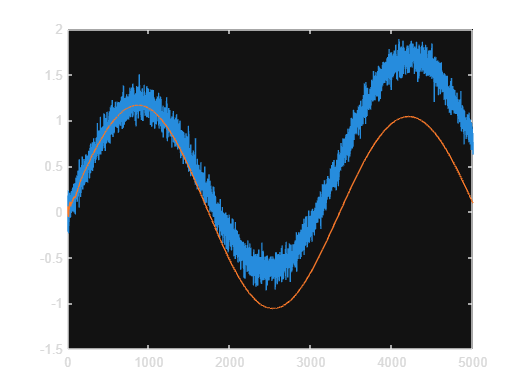

Q = zeros(2);
out_0 = runModel("5000");
plot(out_0.tout, out_0.ybar, ...
    out_0.tout, reshape(out_0.yhat, [length(out_0.yhat), 1]));

## Task 2

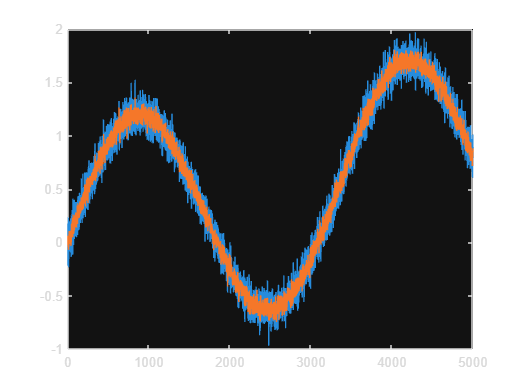

Q = eye(2);
out_1 = runModel("5000");
plot(out_1.tout, out_1.ybar, ...
    out_1.tout, reshape(out_1.yhat, [length(out_1.yhat), 1]));

## Task 3

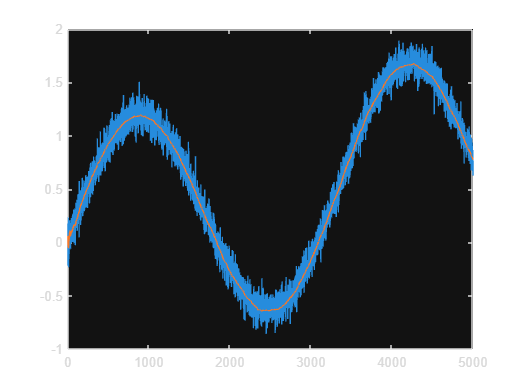

Q = eye(2)*1e-7;
out_optim = runModel("5000");
plot(out_optim.tout, out_optim.ybar, ...
    out_optim.tout, reshape(out_optim.yhat, [length(out_optim.yhat), 1]));